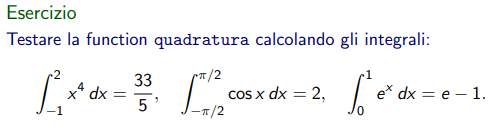

clear all
close all
%f = @(x) x.^4; a = -1; b = 2;
%f = @(x) cos(x); a = -pi/2; b = pi/2;
f = @(x) exp(x); a = 0; b = 1;
I = quadratura(f,a,b,100,1)

I = 1.7183

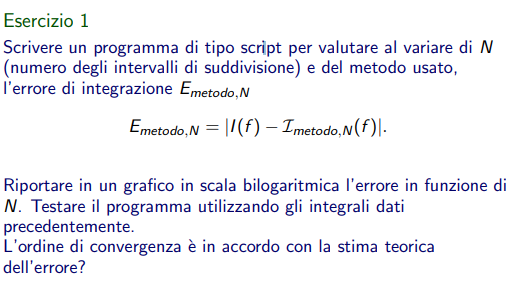

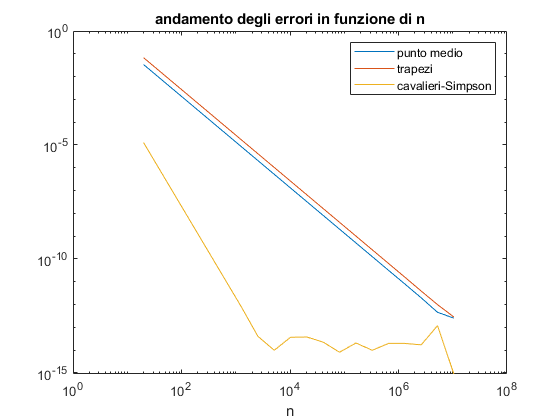

clear all
close all
f = @(x) x.^4; a = -1; b = 2;
I = 33/5;
E = [];
V =[];
H = [];
for n = 1:20
    int = 10*2^n;
    for m = 1:1:3
        I_met = quadratura(f,a,b,int,m);
        E(n,m) = abs(I-I_met);
    end
    H = [H ((b-a)/int)^2];
    V = [V int];
end
figure()
loglog(V,E(:,1))
hold on
loglog(V,E(:,2))
loglog(V,E(:,3))
title("andamento degli errori in funzione di n")
xlabel("n")
legend("punto medio","trapezi","cavalieri-Simpson")

- punto medio e trapezi hanno un andamento pari a H^2

- mentre cavalieri sismpson ha un andamento pari a H^4 raggiunto un valore di n maggiore di 1000 l'integrazione con metodo 3 non migliora

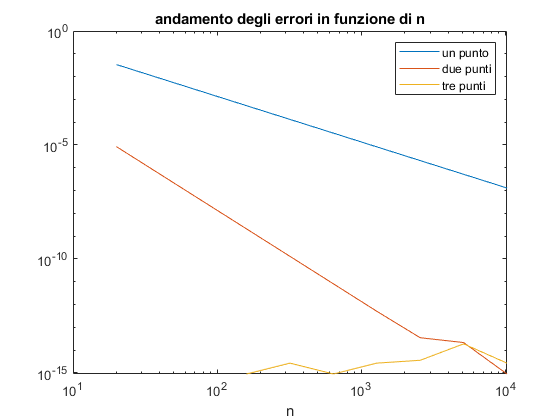

clear all
close all
f = @(x) x.^4; a = -1; b = 2;
I = 33/5;
E = [];
V =[];
H = [];
for n = 1:10
    int = 10*2^n;
    for m = 1:1:3
        I_met = quadGL(f,a,b,int,m);
        E(n,m) = abs(I-I_met);
    end
    H = [H ((b-a)/int)^2];
    V = [V int];
end
figure()
loglog(V,E(:,1))
hold on
loglog(V,E(:,2))
loglog(V,E(:,3))
title("andamento degli errori in funzione di n")
xlabel("n")

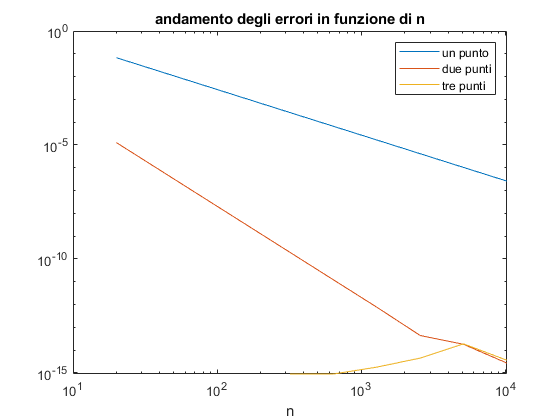

legend("un punto","due punti","tre punti")


E = [];
V =[];
H = [];
for n = 1:10
    int = 10*2^n;
    for m = 1:1:3
        I_met = quadGLL(f,a,b,int,m);
        E(n,m) = abs(I-I_met);
    end
    H = [H ((b-a)/int)^2];
    V = [V int];
end
figure()
loglog(V,E(:,1))
hold on
loglog(V,E(:,2))
loglog(V,E(:,3))
title("andamento degli errori in funzione di n")
xlabel("n")

legend("un punto","due punti","tre punti")


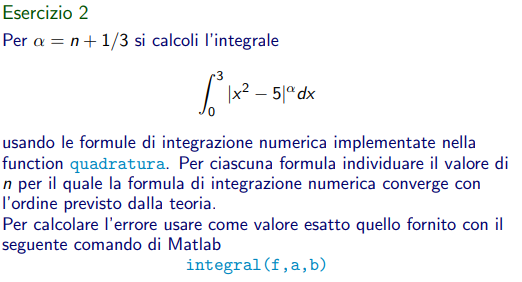

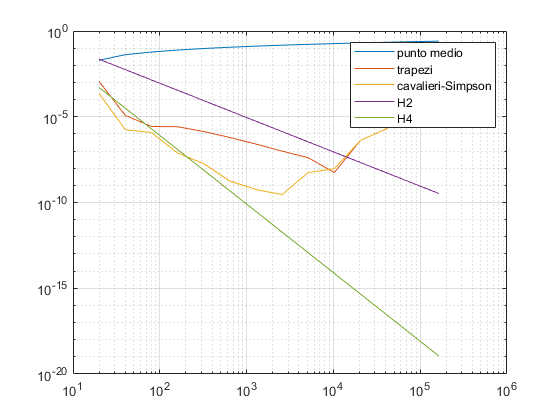

clear all
close all
a = 0; b = 3;

E = [];
V =[];
H2 = [];
H4 = [];

for n = 1:14
    int = 10*2^n;
    for m = 1:1:3
        alpha  = n+1/3;
        f = @(x) abs(x.^2-5).^alpha;
        I = integral(f,a,b);
        I_met = quadGLL(f,a,b,int,m);
        E(n,m) = abs(I-I_met);
    end
    H2 = [H2 ((b-a)/int)^2];
    H4 = [H4 ((b-a)/int)^4];
    V = [V int];
end
loglog(V,E(:,1))
hold on
loglog(V,E(:,2))
loglog(V,E(:,3))
loglog(V,H2)
loglog(V,H4)
grid on

legend("punto medio","trapezi","cavalieri-Simpson","H2","H4")

cavalieri nel'intervallo tra 90 e 110 coverge come previsto dalla teoria mentre i primi due metodi sembra che con i valori di intervallo considerato non convergano. se non i trapezi con valori di intervallo tra 5000e 10000

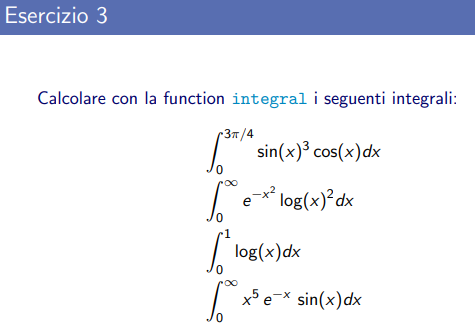

clear all
close all

f  =@(x) sin(x).^3.*cos(x);a = 0;b = 3/4*pi;

I = 0.0625

I = integral(f,a,b)
f  =@(x) exp(-x.^2).*log(x.^2);a = 0;b = inf;

I1 = -1.7401

I1 = integral(f,a,b)
f  =@(x) log(x);a = 0;b = 1;

I2 = -1.0000

I2 = integral(f,a,b)
f  =@(x) x.^5.*exp(-x).*sin(x);a = 0;b = inf;

I3 = -15.0000

I3 = integral(f,a,b)


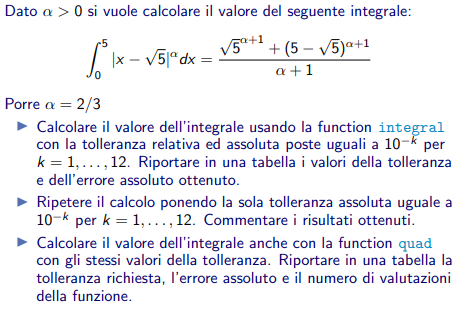

clear all
close all

f = @(x) (abs((x)-sqrt(5))).^(2/3); a  = 0; b = 5;
T = [];
I = (sqrt(5)^(2/3+1)+(5-sqrt(5))^(2/3+1))/((2/3)+1)

I = 5.5603


for  k = 1:1:12
    toll = 10^(-k);
    I1 = integral(f,a,b,"AbsTol",toll,"RelTol",toll);
    I2 = integral(f,a,b,"AbsTol",toll);
    t = [toll abs(I-I1) abs(I-I2)] ;
    T = [T ; t] ;
end
table(T)

ans = 12×1 table
                    T                 
    __________________________________
       0.1     0.0014261     0.0014261
      0.01     0.0014261     0.0014261
     0.001     0.0014261    8.2386e-05
    0.0001    2.0382e-05    2.0382e-05
     1e-05    1.1391e-05    1.5113e-06
     1e-06    1.5113e-06    1.5113e-06
     1e-07    1.0049e-07    1.5113e-06
     1e-08    3.2017e-09    1.5113e-06
     1e-09    2.0445e-09    1.5113e-06
     1e-10    1.2147e-10    1.5113e-06
     1e-11    1.2147e-10    1.5113e-06
     1e-12    3.7659e-13    1.5113e-06